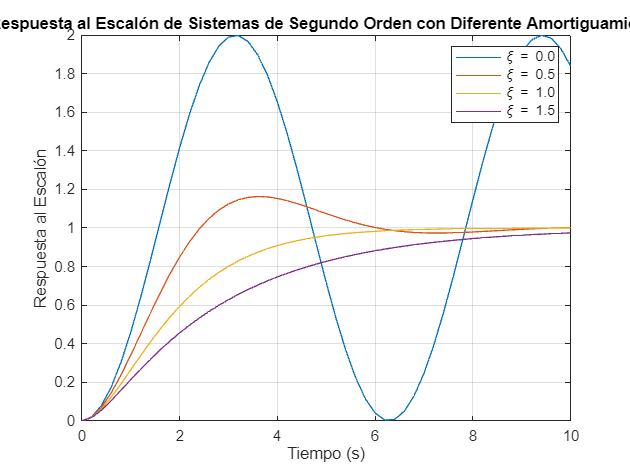

xi = 0:0.5:1.5; % Vector de amortiguamiento
t = 0:0.2:10; % Vector de tiempo

for n = 1:4
    num = [1];
    den = [1 2*xi(n) 1];
    G=tf(num,den);
    [y(1:51,n),t] = step(G,t);
end
plot(t, y)


xlabel('Tiempo (s)') % Etiqueta del eje x
ylabel('Respuesta al Escalón') % Etiqueta del eje y
title('Respuesta al Escalón de Sistemas de Segundo Orden con Diferente Amortiguamiento') % Título
legend(arrayfun(@(xi) sprintf('\\xi = %.1f', xi), xi, 'UniformOutput', false)) % Leyenda
grid on % Mostrar la cuadrícula

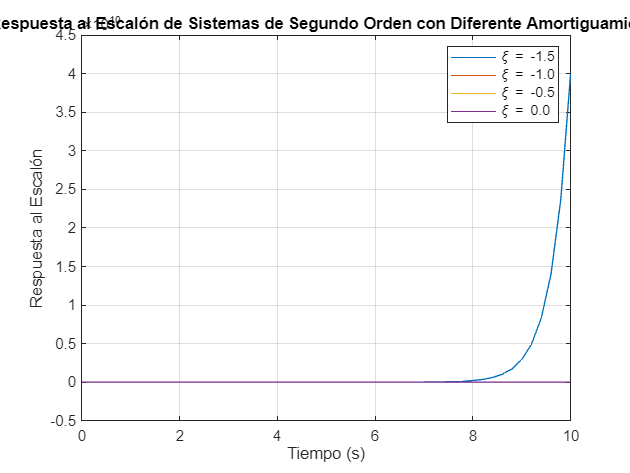

xi = -1.5:0.5:0; % Vector de amortiguamiento
t = 0:0.2:10; % Vector de tiempo

for n = 1:4
    num = [1];
    den = [1 2*xi(n) 1];
    G=tf(num,den);
    [y(1:51,n),t] = step(G,t);
end
plot(t, y)


xlabel('Tiempo (s)') % Etiqueta del eje x
ylabel('Respuesta al Escalón') % Etiqueta del eje y
title('Respuesta al Escalón de Sistemas de Segundo Orden con Diferente Amortiguamiento') % Título
legend(arrayfun(@(xi) sprintf('\\xi = %.1f', xi), xi, 'UniformOutput', false)) % Leyenda
grid on % Mostrar la cuadrícula